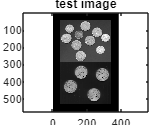

% Define the filter size we will use in step 2:
filtsize = 85;

% Creating test image 'im' by splicing together two built in images.
% Also zero-padding (adding zeros around the border) with half the 
% filter size (filtsize) we will use so that the filter could be 
% centered on any actual image pixel, including those near the border.
% 'coins.png' contains bright nickels and dimes on a dark background
% 'eight.tif' contains dark quarters on a bright background, so we invert it
% to match 'coins.png'
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
imagesc(im);colormap(gray);title('test image');axis equal;

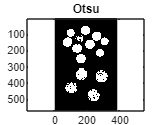


% Initializing assessed/displayed variables as empty so that code is executable 
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[]; 

%%%%% 1. Localize the centroid of each coin
% Otsu threshold
msk = OtsuThreshold(im);

figure; imagesc(msk); colormap(gray); title('Otsu'); axis equal;

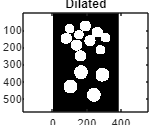


% Dilate 
msk_dil = imdilate(msk,ones(7,7));

figure; imagesc(msk_dil); colormap(gray); title('Dilated'); axis equal;

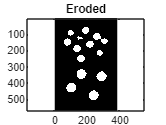


% Erode 

msk_dil_erd = imerode(msk_dil,ones(17,17));
figure; imagesc(msk_dil_erd); colormap(gray); title('Eroded'); axis equal;


% Connected components to get centroids of coins:
CC = bwconncomp(msk_dil_erd);
cc = regionprops(CC,'Centroid');
centroid = zeros(CC.NumObjects, 2);
for i=1:CC.NumObjects   
    centroid(i, :) = round(cc(i).Centroid);
end
component_size = regionprops(CC,'area');


centroid

centroid =     79   149
   103   429
    98    92
   138   188
   153   124
   165   346
   162   251
   191    77
   217   162
   240   477


component_size

component_size = 14×1 struct array with fields:
    Area


% Define the filter size we will use in step 2:
filtsize = 85;

% Creating test image 'im' by splicing together two built in images.
% Also zero-padding (adding zeros around the border) with half the 
% filter size (filtsize) we will use so that the filter could be 
% centered on any actual image pixel, including those near the border.
% 'coins.png' contains bright nickels and dimes on a dark background
% 'eight.tif' contains dark quarters on a bright background, so we invert it
% to match 'coins.png'
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
imagesc(im);colormap(gray);title('test image');axis equal;

% Initializing assessed/displayed variables as empty so that code is executable 
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[]; 

%%%%% 1. Localize the centroid of each coin
% Otsu threshold
msk = OtsuThreshold(im);
figure; imagesc(msk); colormap(gray); title('Otsu'); axis equal;

% Dilate 9x9
msk_dil = imdilate(msk,ones(9,9));
figure; imagesc(msk_dil); colormap(gray); title('Dilated'); axis equal;

% Erode 23x23
msk_dil_erd = imerode(msk_dil,ones(23,23));
figure; imagesc(msk_dil_erd); colormap(gray); title('Eroded'); axis equal;


% Connected components to get centroids of coins:
cc = bwconncomp(msk_dil_erd);
props_struct = regionprops(cc);
centroid = zeros(length(props_struct),2);
component_size = zeros(length(props_struct),1);
for i=1:length(props_struct)
    centroid(i,:) = round(props_struct(i).Centroid);
    component_size(i) = props_struct(i).Area;
end


%%%%% 2. Measure features for each coin using a bank of matching filters
% make matching filters to create features
% Define diameters to use for filters
dimediameter = 31;
quarterdiameter = 51;
nickeldiameter = 41;

% Initialize assessed variables
D=[]; nickelfilter = []; dimefilter = []; quarterfilter = [];

% Use the MakeCircleMatchingFilter function to create matching filters for dimes, nickels, and quarters
% (This is in a separate Matlab grader problem. Save your work, 
%       complete the corresponding grader problem and embed the solution 
%       in the helper function list below.)


figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;

% Evaluate each of the 3 matching filters on each coin to serve as 3 feature measurements 


D

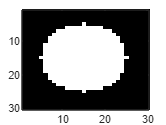

diameter = 20;
W = 30;
[filter, xc, yc] = MakeCircleMatchingFilter(diameter,W);
imagesc(filter); colormap(gray)

xc % should be 15.5

xc = 15

yc % should be 15.5

yc = 15

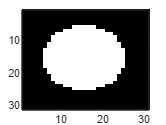


diameter = 20;
W = 31;
[filter, xc, yc] = MakeCircleMatchingFilter(diameter,W);
figure; imagesc(filter); colormap(gray);

xc % should be 16

xc = 15.5000

yc % should be 16

yc = 15.5000

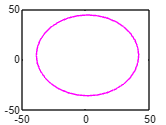

coinvalue = 25

x_plot =    41.2000   40.4314   38.1552   34.4588   29.4843   23.4228   16.5073    9.0036    1.2000   -6.6036  -14.1073  -21.0228  -27.0843  -32.0588  -35.7552  -38.0314  -38.8000  -38.0314  -35.7552  -32.0588  -27.0843  -21.0228  -14.1073   -6.6036    1.2000    9.0036   16.5073   23.4228   29.4843   34.4588   38.1552   40.4314   41.2000


y_plot =     4.1000   11.9036   19.4073   26.3228   32.3843   37.3588   41.0552   43.3314   44.1000   43.3314   41.0552   37.3588   32.3843   26.3228   19.4073   11.9036    4.1000   -3.7036  -11.2073  -18.1228  -24.1843  -29.1588  -32.8552  -35.1314  -35.9000  -35.1314  -32.8552  -29.1588  -24.1843  -18.1228  -11.2073   -3.7036    4.1000


col = 'm'

x=1.2;
y=4.1;  
cls = 3;
[coinvalue,x_plot,y_plot,col] = AddCoinToPlotAndCount(x,y,cls)

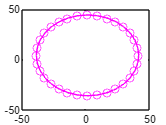

figure
plot(x_plot,y_plot,[col,'o-'])

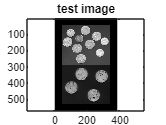

% Define the filter size we will use in step 2:
filtsize = 85;

% Creating test image 'im' by splicing together two built in images.
% Also zero-padding (adding zeros around the border) with half the 
% filter size (filtsize) we will use so that the filter could be 
% centered on any actual image pixel, including those near the border.
% 'coins.png' contains bright nickels and dimes on a dark background
% 'eight.tif' contains dark quarters on a bright background, so we invert it
% to match 'coins.png'
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
imagesc(im);colormap(gray);title('test image');axis equal;


% Initializing assessed/displayed variables as empty so that code is executable 
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[]; 

%%%%% 1. Localize the centroid of each coin
% Otsu threshold
msk = OtsuThreshold(im);
figure; imagesc(msk); colormap(gray); title('Otsu'); axis equal;

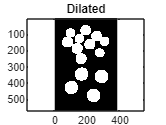


% Dilate 9x9
msk_dil = imdilate(msk,ones(9,9));
figure; imagesc(msk_dil); colormap(gray); title('Dilated'); axis equal;

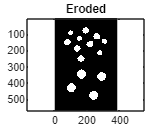


% Erode 23x23
msk_dil_erd = imerode(msk_dil,ones(23,23));
figure; imagesc(msk_dil_erd); colormap(gray); title('Eroded'); axis equal;

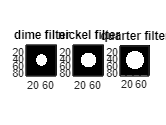



% Connected components to get centroids of coins:
cc = bwconncomp(msk_dil_erd);
props_struct = regionprops(cc);
centroid = zeros(length(props_struct),2);
component_size = zeros(length(props_struct),1);
for i=1:length(props_struct)
    centroid(i,:) = round(props_struct(i).Centroid);
    component_size(i) = props_struct(i).Area;
end


%%%%% 2. Measure features for each coin using a bank of matching filters
% make matching filters to create features
% Define diameters to use for filters
dimediameter = 31;
quarterdiameter = 51;
nickeldiameter = 41;

% Initialize assessed variables
D=[]; nickelfilter = []; dimefilter = []; quarterfilter = [];

% Use the MakeCircleMatchingFilter function to create matching filters for dimes, nickels, and quarters
% (This is in a separate Matlab grader problem. Save your work, 
%       complete the corresponding grader problem and embed the solution 
%       in the helper function list below.)
[dimefilter, xc, yc] = MakeCircleMatchingFilter(dimediameter,filtsize);
[quarterfilter, xc, yc] = MakeCircleMatchingFilter(quarterdiameter,filtsize);
[nickelfilter, xc, yc] = MakeCircleMatchingFilter(nickeldiameter,filtsize);


figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;


% Evaluate each of the 3 matching filters on each coin to serve as 3 feature measurements 
for i=1:size(centroid,1)
 for j=1:3
     filt = dimefilter;
     if j == 2
         filt = nickelfilter;
     elseif j == 3
         filt = quarterfilter;
     end
     x = centroid(i,1);
     y = centroid(i,2);
     D(i,j) = corr(filt(:), reshape(msk_dil_erd(y-filtsizeh:y+filtsizeh, x-filtsizeh:x+filtsizeh),[], 1));
 end
end
D

D =     0.7237    0.9180    0.7013
    0.4948    0.6857    0.9160
    0.8499    0.6177    0.4439
    0.7157    0.9260    0.7044
    0.7801    0.5502    0.3817
    0.4932    0.6835    0.9138
    0.7196    0.9573    0.7453
    0.7392    0.8675    0.6413
    0.6415    0.8135    0.6234
    0.4858    0.6732    0.9001


% Define the filter size we will use in step 2:
filtsize = 85;

% Creating test image 'im' by splicing together two built in images.
% Also zero-padding (adding zeros around the border) with half the 
% filter size (filtsize) we will use so that the filter could be 
% centered on any actual image pixel, including those near the border.
% 'coins.png' contains bright nickels and dimes on a dark background
% 'eight.tif' contains dark quarters on a bright background, so we invert it
% to match 'coins.png'
im1 = imread('coins.png');
[r,c] = size(im1);
im2 = imread('eight.tif');
[r2,c2] = size(im2);
filtsizeh = floor(filtsize/2);
im = zeros(r+r2+filtsize,c+filtsize);
im(filtsizeh+1:filtsizeh+r+r2,filtsizeh+1:filtsizeh+c) = [im1;255-im2(:,1:c)];
[r,c] = size(im);
imagesc(im);colormap(gray);title('test image');axis equal;

% Initializing assessed/displayed variables as empty so that code is executable 
msk=[]; msk_dil=[]; msk_dil_erd=[]; centroid=[]; component_size=[]; 

%%%%% 1. Localize the centroid of each coin
% Otsu threshold
msk = OtsuThreshold(im);
figure; imagesc(msk); colormap(gray); title('Otsu'); axis equal;

% Dilate 9x9
msk_dil = imdilate(msk,ones(9,9));
figure; imagesc(msk_dil); colormap(gray); title('Dilated'); axis equal;


% Erode 23x23
msk_dil_erd = imerode(msk_dil,ones(23,23));
figure; imagesc(msk_dil_erd); colormap(gray); title('Eroded'); axis equal;



% Connected components to get centroids of coins:
cc = bwconncomp(msk_dil_erd);
props_struct = regionprops(cc);
centroid = zeros(length(props_struct),2);
component_size = zeros(length(props_struct),1);
for i=1:length(props_struct)
    centroid(i,:) = round(props_struct(i).Centroid);
    component_size(i) = props_struct(i).Area;
end


%%%%% 2. Measure features for each coin using a bank of matching filters
% make matching filters to create features
% Define diameters to use for filters
dimediameter = 31;
quarterdiameter = 51;
nickeldiameter = 41;

% Initialize assessed variable D
D=[]; nickelfilter = []; dimefilter = []; quarterfilter = [];

% Use the MakeCircleMatchingFilter function to create matching filters for dimes, nickels, and quarters
% (This is in a separate Matlab grader problem. Save your work, 
%       complete the corresponding grader problem and embed the solution 
%       in the helper function list below.)
nickelfilter = MakeCircleMatchingFilter(nickeldiameter,filtsize);
dimefilter = MakeCircleMatchingFilter(dimediameter,filtsize);
quarterfilter = MakeCircleMatchingFilter(quarterdiameter,filtsize);

figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;


% Evaluate each of the 3 matching filters on each coin to serve as 3 feature measurements 
D = zeros(length(centroid),3);
for i=1:length(centroid)
    D(i,1) = corr(dimefilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,2) = corr(nickelfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));
    D(i,3) = corr(quarterfilter(:),reshape(msk_dil_erd(centroid(i,2)-filtsizeh:...
        centroid(i,2)+filtsizeh,centroid(i,1)-filtsizeh:centroid(i,1)+filtsizeh),[filtsize*filtsize,1]));    
end

figure;
subplot(1,3,1); imagesc(dimefilter); colormap(gray); title('dime filter'); axis tight equal;
subplot(1,3,2); imagesc(nickelfilter); colormap(gray); title('nickel filter'); axis tight equal;
subplot(1,3,3); imagesc(quarterfilter); colormap(gray); title('quarter filter'); axis tight equal;


%%%%% 3. Perform k-means clustering of features for unsupervised learning classifier
rng(0);
cls_init=[]; cls=[]; totcount=[];
[cls_init,~] = kmeans(D,3);

cls_init

cls_init =      3
     1
     2
     3
     2
     1
     3
     3
     3
     1


% relabel centroid classes based on average size of the objects in each class. smallest will be dime, next nickel, and largest quarter
class_ave_object_size = zeros(3,1);
for i=1:3
    class_ave_object_size(i) = mean(component_size(cls_init==i));
end

[~,clsmap] = sort(class_ave_object_size);
%class_ave_object_size
%clsmap

for i=1:size(centroid,1)
    %cls(i) = clsmap(cls_init(i));
    for j=1:3
      if cls_init(i) == clsmap(j)
        cls(i) = j;
      end
    end
end

cls = cls';

cls

cls =      2
     3
     1
     2
     1
     3
     2
     2
     2
     3


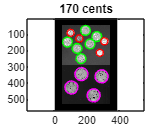

% Visualize the result
figure; imagesc(im);colormap(gray);title('test image');hold on;axis equal;

% plot circles around each coin with different color/diameter unique to each type and count the change
totcount = 0;
for i=1:size(centroid,1)
    x = centroid(i,1);
    y = centroid(i,2);
    [coinvalue,~,~,~] = AddCoinToPlotAndCount(x,y,cls(i));
    totcount = totcount + coinvalue;
end

title([num2str(totcount),' cents'])

%%%%%%%%%%%%%%%%%%%% Helper Functions %%%%%%%%%%%%%%%%%%%%%

function [msk,thrsh] = OtsuThreshold(im)
hst = imhist(im);
res = otsuthresh(hst);
thrsh = res*255;
msk = im>thrsh;
end

function [coinvalue,x_plot,y_plot,col] = AddCoinToPlotAndCount(x,y,cls)
% initialize radians for defining x_plot and y_plot using cos and sin functions
rads = 0:2*pi/32:2*pi;
% initialize parameters for radius and color of circle for each type of coin
r = 22;
col = 'r';
% use if-elseif statement to define x_plot, y_plot, col
%   when cls is 1, we found a dime
if cls == 1
    coinvalue = 10;
    r = 22;
    col = 'r';
%   when cls is 2, we found a nickel
elseif cls == 2
    coinvalue = 5;
    r = 30;
    col = 'g';
%   when cls is 3, we found a quarter
elseif cls == 3
    coinvalue = 25;
    r = 40;
    col = 'm';
end
x_plot = x+r*cos(rads);
y_plot = y+r*sin(rads);
plot(x_plot,y_plot,col);
end

%%%%%%%%%%%%%%%%%%%% Helper Functions %%%%%%%%%%%%%%%%%%%%%
function [filter,xc,yc] = MakeCircleMatchingFilter(diameter,W)
% initialize filter
filter = zeros(W, W);
% define coordinates for the center of the WxW filter
xc = (W+1)/2;
yc = (W+1)/2;
% Use double-for loops to check if each pixel lies in the foreground of the circle
r = diameter / 2;
for i=1:W
    for j=1:W
        if (i-xc)^2 + (j-yc)^2 <= r^2
            filter(i,j) = 1;
        end
    end
end

end
